## Task 2.2: two word classification

From the confusion matrix you need to select two words for which the performance was the best. Train the new model with only those two words and test it on an independent test set. It is important to look at the features that can be used to separate between words. This information will be useful in the module of voice processing.

We should now make a data matrix only containing the two words with the best performance results. We will assign the outputs to class "1" and "2".

X =  [Word5;Word7];
Y =  [ones(40,1);2*ones(40,1)]; 

### Train-test split indices

percent_train_split=70/100;
train_id=[];
test_id=[];
num_classes=length(unique(Y)); 

% loop through the classes
for i=1:num_classes 
    % % finding the indices belonging to each class: use find()
    ind_i = find(Y==i);
    
    % %shuffling the indice
    ind_i_perm=ind_i(randperm(length(ind_i)));
    
    % % the split point for train test
    ind_split= percent_train_split * length(ind_i_perm);
    
    % % adding the train ids to the the previous ids 
    train_id= [train_id; ind_i_perm(1:ind_split)];
    
    % % adding the test ids to the the previous ids 
    test_id= [test_id; ind_i_perm(ind_split+1:length(ind_i_perm))]; 
    
end

### Split the data

% % splitting the inputs
% complete the codes below
Xtrain= X(train_id,1:25);
Xtest= X(test_id,1:25);

% % splitting the labels
Ytrain= Y(train_id,1);
Ytest= Y(test_id,1);

### Normalize the data

[Xtrain,mu_train,sigma_train] = zscore(Xtrain);
Xtest= (Xtest-mu_train)./sigma_train;

### Feature Selection using mRMR

As before, we perform feature selection using mRmR 

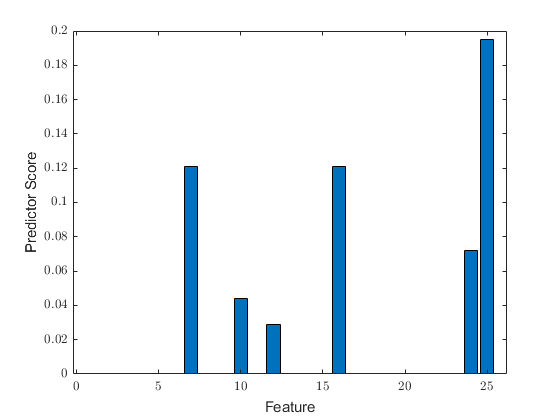

[idx,scores] = fscmrmr(Xtrain,Ytrain);
figure(1);
bar(idx,scores(idx)) % Create bar graph
xlabel('Feature')
set(gca,'TickLabelInterpreter','latex');
ylabel('Predictor Score');
hold off;

we select 3 features with the best importance and onlytrain the model with them. From the plot above find the 3 indices with the highest score and use them in the code below for feature selection (rerun the whole code  a few times of you don't get a nice plot, the result depend on train/test split to some extent.)

[values, sel_feat]= maxk(scores,3);
Xtrain=Xtrain(:,sel_feat);
Xtest=Xtest(:,sel_feat);

### Train the classifier 

% This makes sure we get the same results every time we run the code.
rng default

% How many trees do you want in the forest? 
nTrees = 100;
 
% Train the TreeBagger (Random Forest).
model = TreeBagger( nTrees,Xtrain,Ytrain ...
    , 'Method', 'classification');

### Predict outputs for test data

Ytest_pred_str = model.predict(Xtest);
Ytest_pred =  str2double(Ytest_pred_str);

### Turn the numerical outputs to categorial

Ytest_cat= zeros(num_classes,length(Ytest));
Ytest_pred_cat= zeros(num_classes,length(Ytest_pred));

for i=1:num_classes
    Ytest_cat(i, Ytest==i) = 1;
    Ytest_pred_cat(i, Ytest_pred==i) = 1;
end

### Plot the confusion matrix

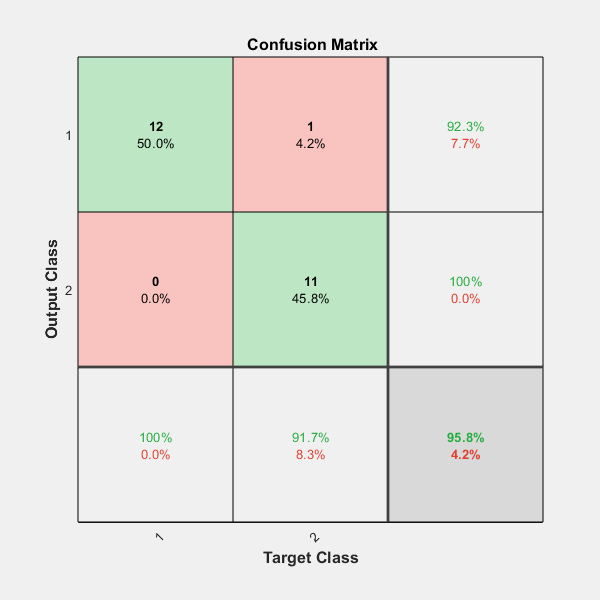

figure(2);
plotconfusion(Ytest_cat, Ytest_pred_cat);